%%Laboratorio 3 Entregables de clase
%%Keren Gamarro Sección 11 Procesamiento de Señales 23546-Pedro Castillo

%%Ejercicio 1: Probar 5 vueltas usando la funcion h y sin usarla, sacar
%%promedios
% Vueltas sin h
valores_sin_h = [1.799136 1.796692 1.827172 1.810095 1.825969];

% Promedio
promedio_sin_h = mean(valores_sin_h);

% Resultado
disp('El promedio de los valores es:')

El promedio de los valores es:


disp(promedio_sin_h)

    1.8118



% Valores con h
valores_con_h = [0.617980
0.606320
0.602843
0.602682
0.594593];

% Promedio
promedio_con_h = mean(valores_con_h);

% Resultado
disp('El promedio de los valores es:')

El promedio de los valores es:


disp(promedio_con_h)

    0.6049



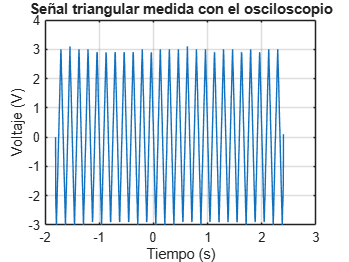

%%Ejercicio 2: Cargar archivo antes realizado, luego graficar, obtener
%%numero de muestras periodo voltajes maximos minimos promedio y presentar
%%resultados
%1 recuperar datos
load('datos_osciloscopio.mat')   % Carga los vectores t y v al Workspace

% 2 Graficar la señal (voltaje vs tiempo)
figure
plot(t, v)
xlabel('Tiempo (s)')
ylabel('Voltaje (V)')
title('Señal triangular medida con el osciloscopio')
grid on


% 3 numero de muestras
N = length(v);    % Número total de muestras de la señal

%4 periodo de muestreo
Ts = t(2) - t(1); % Diferencia entre dos muestras consecutivas de tiempo

% 5 voltaje maximo minimo promedio
v_max = max(v);     % Voltaje máximo
v_min = min(v);     % Voltaje mínimo
v_prom = mean(v);   % Voltaje promedio

%% Mostrar resultados en la ventana de comandos
disp('Resultados del análisis de la señal:')

Resultados del análisis de la señal:


disp(['Número de muestras: ', num2str(N)])

Número de muestras: 1315


disp(['Período de muestreo Ts: ', num2str(Ts), ' s'])

Período de muestreo Ts: 0.0032 s


disp(['Voltaje máximo: ', num2str(v_max), ' V'])

Voltaje máximo: 3.1 V


disp(['Voltaje mínimo: ', num2str(v_min), ' V'])

Voltaje mínimo: -3 V


disp(['Voltaje promedio: ', num2str(v_prom), ' V'])

Voltaje promedio: -0.0047148 V



%¿Cómo se compara la señal observada en la imagen del osciloscopio con la graficada en Matlab? ¿Se parecen?
% Se parecen ya que ambas son triangulares, periodicas y con pendientes
% lineales.
% ¿Cuál es la amplitud de la señal? Puede usar lo calculado anteriormente para obtener esto.
%Es de 3.05V, se saca restando voltaje maximo menos minimo y diviendo en 2

%%Ejercicio 3:Cree 3 vectores numéricos distintos y aplíqueles la función PS_Lab3_fun1. Llame a la función desde la ventana de comandos, y desde el script aparte. Tenga cuidado con los argumentos de entrada y salida


%% Vectores distintos
v1 = [1 2 3 4 5];          % Vector 1
v2 = [-2 0 2 4 6 8];       % Vector 2
v3 = [10 8 6 4 2];         % Vector 3

%% Se llama a la función PS_Lab3_fun1 desde el script
% Se capturan todas las salidas de la función
[mu1, s1, M1, m1, Suma1] = PS_Lab3_fun1(v1);   % Resultados para v1
[mu2, s2, M2, m2, Suma2] = PS_Lab3_fun1(v2);   % Resultados para v2
[mu3, s3, M3, m3, Suma3] = PS_Lab3_fun1(v3);   % Resultados para v3

%% Se llama desde la command window

% PS_Lab3_fun1(v1)
% Ejecuta la función y muestra los resultados, pero no los guarda

% [a, b, c, d, e] = PS_Lab3_fun1(v2)
% Ejecuta la función y muestra las salidas porque no hay punto y coma

% [a, b, c, d, e] = PS_Lab3_fun1(v3);
% Ejecuta la función, guarda los resultados, pero no los muestra

% PS_Lab3_fun1(v3);
% Ejecuta la función sin guardar las salidas (los resultados se pierden)